clc;
clear all;
l1=30; %Length of Link 1
l2=30; %Length of Link 2
l3=10;  %Length of Link 3
l4 =10; %Length of Link 4
% DHparameter=[0 pi/2 0.04 0;
%              0.12 0 0 13*pi/30+pi/2;
%              0.194 -pi/2 0 -23*pi/30+pi/2;
%              0 0 0.176 0;
%              0 pi/2 0 pi/2;
%              0 0 0 0]
% a alpha d theta
% DHparameter=[0 pi/2 40 0;
%              120 0 0 13*pi/30+pi/2;
%              194 -pi/2 0 -23*pi/30+pi/2;
%              0 0 176 0;
%              0 pi/2 0 pi/2;
%              0 0 0 0;
%              50 0 0 pi]
DHparameter = [0 0 40 0;
               120 pi/2 0 13*pi/30;
               194 0 0 -23*pi/30;
               0 -pi/2 176 0;
               0 pi/2 0 pi/2;
               0 -pi/2 0 0;
               50 0 0 0];

## `Defining the asymmetric robot as a rigid tree`

%Defining a Robot Rigid Body Tree 
dental = rigidBodyTree("MaxNumBodies",6,"DataFormat","column");

%Setting the Gravity matrix w.r.t to the base frame of robot.
dental.Gravity = [0 0 -9.81];

%Creating links and joints
body1 = rigidBody('Body1');
joint1 = rigidBodyJoint('Joint1','revolute');
joint1.PositionLimits = [0 2*pi];
body1.Mass = 10;
body1.CenterOfMass = [0 0 0];

body2 = rigidBody('Body2');
joint2 = rigidBodyJoint('Joint2','revolute');
% joint2.HomePosition = 13*pi/30+pi/2;
% joint2.PositionLimits = [0 23*pi/33];
body2.Mass = 10;
body2.CenterOfMass = [0 0 0];

body3 = rigidBody('Body3');
joint3 = rigidBodyJoint('Joint3','revolute');
body3.Mass = 10;
% joint3.HomePosition = -23*pi/30+pi/2;
% joint3.PositionLimits = [-pi/3 pi/3]; %Position limit defines the maximum extension/retraction from mean position for a prismatic joint. 
body3.CenterOfMass = [0 0 0];

body4 = rigidBody('Body4');
joint4 = rigidBodyJoint('Joint4','revolute');
body4.Mass = 10;
% joint4.PositionLimits = [0 2*pi];

body5 = rigidBody('Body5');
joint5 = rigidBodyJoint('Joint5','revolute');
% joint5.HomePosition = pi/2;
% joint5.PositionLimits = [-pi/4 pi/4];
body5.Mass = 10;

body6 = rigidBody('Body6');
joint6 = rigidBodyJoint('Joint6','revolute');
% joint6.PositionLimits = [-pi/4 pi/4];
body6.Mass = 10;

body7 = rigidBody('Body7');
joint7 = rigidBodyJoint('Joint7','prismatic');
% joint7.PositionLimits = [0 75];
body7.Mass = 10;

%Settings the transformations to each joint with DH parameter.
%Assigning the joint of each link with the object 
setFixedTransform(joint1,DHparameter(1,:),"mdh");
body1.Joint = joint1;
setFixedTransform(joint2,DHparameter(2,:),"mdh");
body2.Joint = joint2;
setFixedTransform(joint3,DHparameter(3,:),"mdh");
body3.Joint = joint3;
setFixedTransform(joint4,DHparameter(4,:),"mdh");
body4.Joint = joint4;
setFixedTransform(joint5,DHparameter(5,:),"mdh");
body5.Joint = joint5;
setFixedTransform(joint6,DHparameter(6,:),"mdh");
body6.Joint = joint6;
setFixedTransform(joint7,DHparameter(7,:),"mdh");
body7.Joint = joint7;

addBody(dental,body1,'base');
addBody(dental,body2,'Body1');
addBody(dental,body3,'Body2');
addBody(dental,body4,'Body3');
addBody(dental,body5,'Body4');
addBody(dental,body6,'Body5');
addBody(dental,body7,'Body6');

collisionObj = [collisionCylinder(0.05,0.12);
                collisionCylinder(0.05,0.12);
                collisionCylinder(0.05,0.12);
                collisionCylinder(0.05,0.12);
                collisionCylinder(0.05,0.12);
                collisionCylinder(0.05,0.12);
                collisionCylinder(0.05,0.12)]

collisionObj =   7×1 collisionCylinder array with properties:

    Radius
    Length
    Pose


for i = 1:dental.NumBodies
    addCollision(dental.Bodies{i},collisionObj(i,1));
end

showdetails(dental)

--------------------
Robot: (7 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1      revolute             base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  
   6        Body6        Joint6      revolute            Body5(5)   Body7(7)  
   7        Body7        Joint7     prismatic            Body6(6)   
--------------------


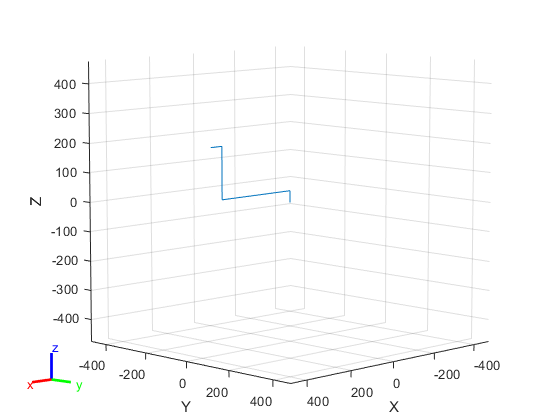


figure
    show(dental);

## `Denture, 3 - Teeth, 1 - Tooth, Final Tooth, Transformation and Shrink`

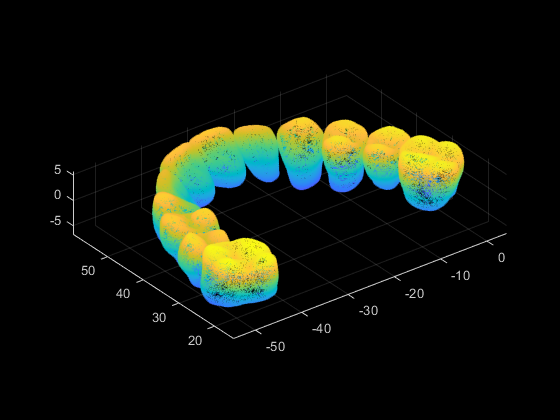

% Read and plot complete denture
stlData = stlread('1-3dm.stl');
points = stlData.Points;
ptCloud = pointCloud(points);
figure
pcshow(ptCloud)

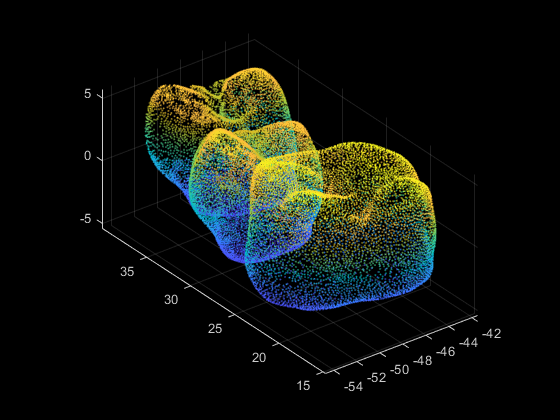


% Select and plot three teeth individually
roi = [-60 -40 10 40 -6 6]; % region of interest
indices = findPointsInROI(ptCloud,roi);
ptCloudB = select(ptCloud, indices);
pcshow(ptCloudB.Location);

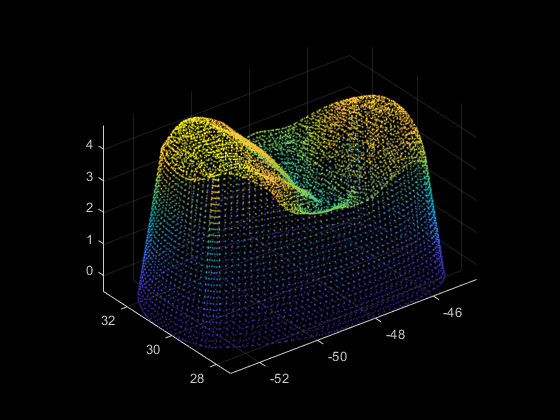


% Import and plot final model individually
stlData_fin = stlread("1tooth_mesh2.STL");

points_fin= stlData_fin.Points;
ptCloud_fin = pointCloud(points_fin);
pcshow(ptCloud_fin);

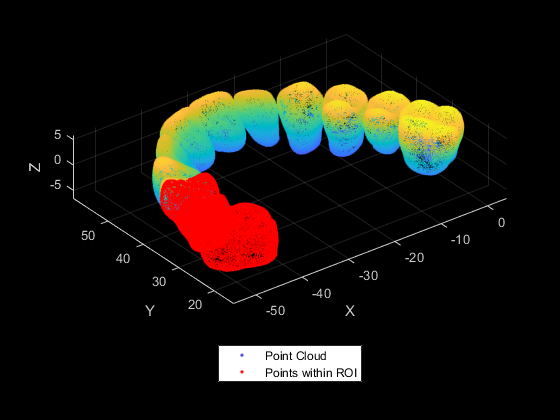


% Three teeth in the denture
figure
pcshow(ptCloud);
hold on;
pcshow(ptCloudB.Location,'r');
legend('Point Cloud','Points within ROI','Location','southoutside','Color',[1 1 1])
xlabel('X'); ylabel('Y'); zlabel('Z');
hold off;

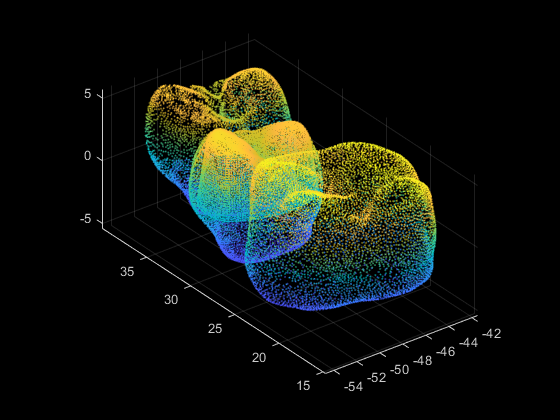


% Final tooth inside the considered tooth
figure
pcshow(ptCloudB.Location);
hold on;
pcshow(ptCloud_fin);
hold off;

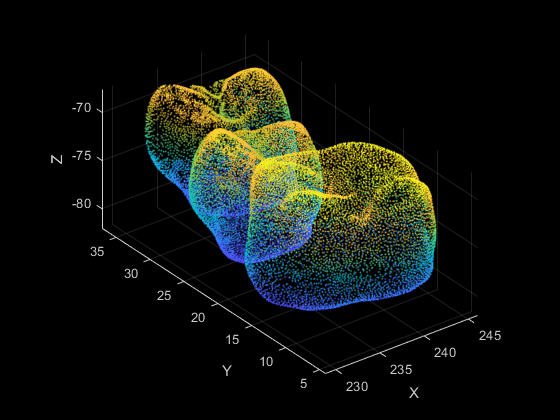


%Transformation (shrink and move)
Sx = 1.3;
Sy = 1.3;
Sz = 1.3;


tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
ptCloud_3t = pctransform(ptCloudB,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);
rot = [1 0 0; 0 1 0; 0 0 1];
zCoord = -75;
trans = 1000*[0.300 -0.015 zCoord/1000];
rigid_tform = rigid3d(rot,trans);
ptCloud_3t = pctransform(ptCloud_3t,rigid_tform);
ptCloud_fin = pctransform(ptCloud_fin,rigid_tform);

figure
pcshow(ptCloud_3t)
xlabel('X'); ylabel('Y'); zlabel('Z')

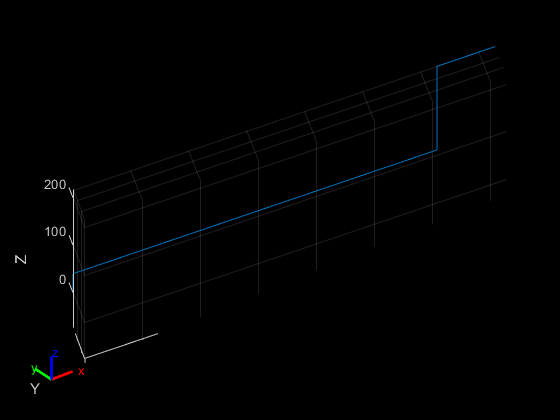

pcshow(ptCloud_fin)
xlabel('X'); ylabel('Y'); zlabel('Z')
hold on
show(dental);

## `STL files for neighboring teeth`

stlData = stlread('Single_Back_tooth.stl');
points = stlData.Points;
backTooth = pointCloud(points);

stlData = stlread('Single_front_tooth.stl');
points = stlData.Points;
frontTooth = pointCloud(points);

% frontTooth = pctransform(frontTooth,tform);
% frontTooth = pctransform(frontTooth,rigid_tform);

%Merge
neighboringTeeth = pcmerge(frontTooth, backTooth, 1);

%Transformation (shrink and move)
neighboringTeeth = pctransform(neighboringTeeth,tform);
neighboringTeeth = pctransform(neighboringTeeth,rigid_tform);


% pcshow(neighboringTeeth)
% xlabel('X'); ylabel('Y'); zlabel('Z')

## `Curves for end-effector path planning`

Algo

- set Z range

- get Z -> getContour

- get ordered points -> getOrderedPoints()

- smoothen curve -> smoothCurve()

- Make polyshape

- Expand polyshape

figure
allPoints = {};
r = 0.5

r = 0.5000

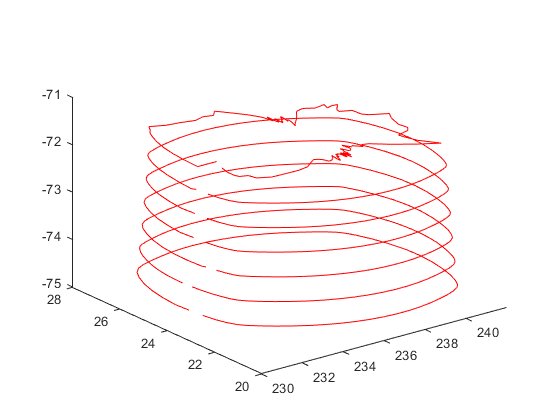

for i=1:7
    L = zCoord + (i-1)*r;
    H = zCoord + r + (i-1)*r;
    [a,b] = getContour(ptCloud_fin,L,H);
    P = getOrderedPoints(a,b);
    [smoothX,smoothY] = smoothCurve(P,35,2);
    
    points = downsample([smoothX',smoothY'],5);
   
    polyin = polyshape({points(:,1)},{points(:,2)});
    polyout = polybuffer(polyin,0.01);
    
    zin = (L+H)/2 * ones(length(polyin.Vertices),1);
    allPoints{i} = [points,zin];
%     zout = (L+H)/2 * ones(length(polyout.Vertices));
    
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),zin,"Color",[1 0 0]); hold on;
%     plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),zout,"Color",[0 1 0]);
end

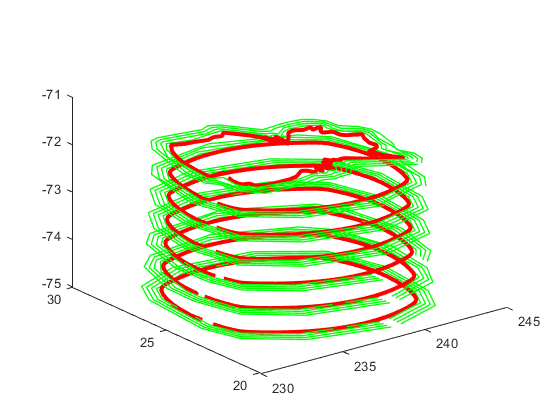

figure
for i=1:length(allPoints)
    polyin = polyshape({allPoints{1,i}(:,1)},{allPoints{1,i}(:,2)});
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),allPoints{1,i}(:,3),...
            "Color",[1 0 0],"LineWidth",3);
    hold on;
    for j=1:4
        polyout = polybuffer(polyin,0.2*j);
        polyout.Vertices = downsample(polyout.Vertices,20);
        z = allPoints{1,i}(1,3)*ones(length(polyout.Vertices),1);
        allPoints{j+1,i} = [polyout.Vertices, z];
        plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),z,...
                "Color",[0 1 0],"LineWidth",1);
    end
end

allPoints

allPoints = 5×7 cell array
    {57×3 double}    {76×3 double}    {68×3 double}    {57×3 double}    {57×3 double}    {58×3 double}    {145×3 double}
    {13×3 double}    {14×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    {14×3 double}    { 60×3 double}
    {13×3 double}    {14×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    {14×3 double}    { 46×3 double}
    {13×3 double}    {14×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    {14×3 double}    { 40×3 double}
    {13×3 double}    {14×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    { 35×3 double}


% Row = Top to Bottom - Inside to Outside
% Column = Left to Right - Bottom to Top

## `Save all quarters in arrays`

curve1 = allPoints{5,1}

curve1 =   237.9255   19.8728  -74.7500
  233.6265   20.6280  -74.7500
  231.1622   22.0348  -74.7500
  230.5175   23.5365  -74.7500
  230.8811   26.6867  -74.7500
  231.7263   27.8323  -74.7500
  234.4792   28.5931  -74.7500
  238.8636   28.1596  -74.7500
  241.7712   26.7023  -74.7500
  242.7407   24.4631  -74.7500


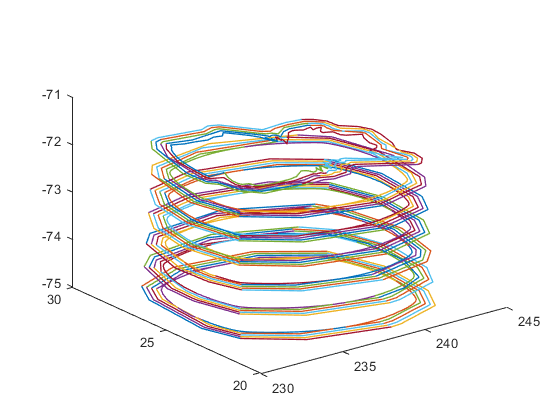

appendAllPoints = [];
figure

for i=1:7
    for j = 1:2 %Offsetting inner most contour fix
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        q1_arr{i,j} = q2;
        q2_arr{i,j} = q1;
        q3_arr{i,j} = q4;
        q4_arr{i,j} = q3;
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
    for j=2:5
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        q1_arr{i,j} = q1;
        q2_arr{i,j} = q2;
        q3_arr{i,j} = q3;
        q4_arr{i,j} = q4;
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
end

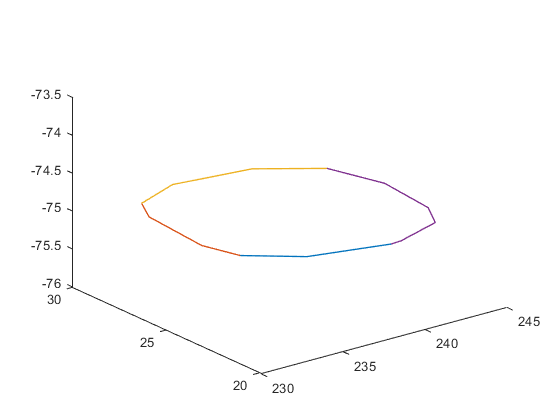

% Show a single curve.
figure
[q1,q2,q3,q4] = getQuarters(allPoints{5,1},1);


% q2 is front
% q1 is right
% q3 is left
% q4 is back

## `Splitting Geometry and Forming into Trajectory`

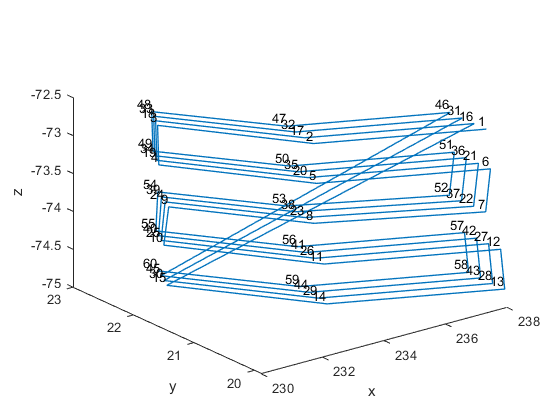

%Plot a single quarter
% figure
% for i=1:5
%     for j=1:5
%         plot3(q1_arr{i,j}(:,1),q1_arr{i,j}(:,2),q1_arr{i,j}(:,3),"LineWidth",1);hold on;
%     end
% end

q1_traj_arr = orderQuarter(q1_arr);
q2_traj_arr = orderQuarter(q2_arr);
q3_traj_arr = orderQuarter(q3_arr);
q4_traj_arr = orderQuarter(q4_arr);

q1_traj_arr_fixed = [];
for i = 1:60
    q1_traj_arr_fixed(i,:) = q1_traj_arr(i,:);
end

q2_traj_arr_fixed = [];
for i = 1:80
    q2_traj_arr_fixed(i,:) = q2_traj_arr(i,:);
end

q3_traj_arr_fixed = [];
for i = 1:80
    q3_traj_arr_fixed(i,:) = q3_traj_arr(i,:);
end

q4_traj_arr_fixed = [];
for i = 1:124
    q4_traj_arr_fixed(i,:) = q4_traj_arr(i,:);
end

save fixed_contour.mat q1_traj_arr_fixed q2_traj_arr_fixed q3_traj_arr_fixed q4_traj_arr_fixed

figure
plotQuarter(q1_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

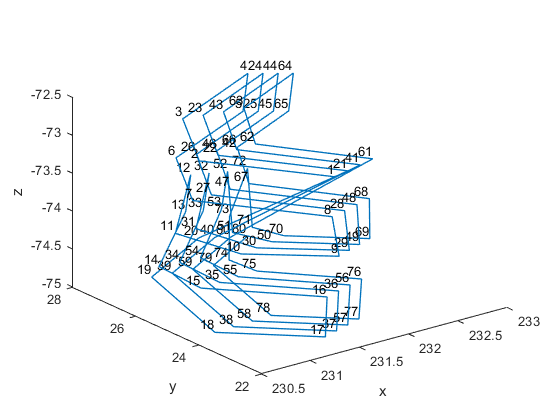

plotQuarter(q2_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

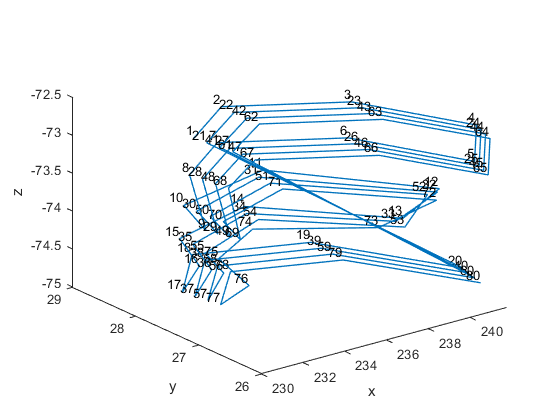

plotQuarter(q3_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

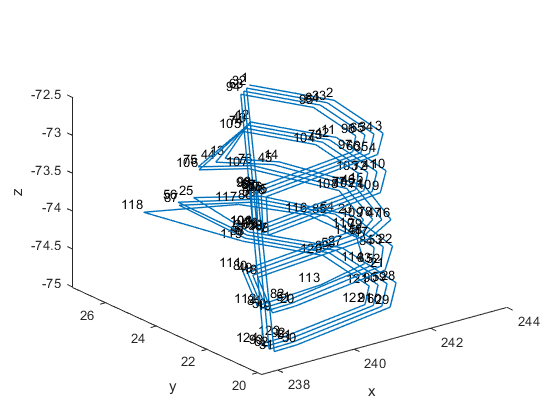

plotQuarter(q4_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');
hold off

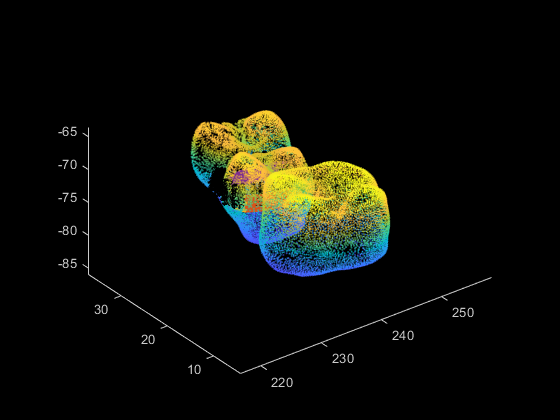


figure
hold on
pcshow(ptCloud_3t)
plotQuarter(q1_traj_arr_fixed);
plotQuarter(q2_traj_arr_fixed);
plotQuarter(q3_traj_arr_fixed);
plotQuarter(q4_traj_arr_fixed);

## `Calculate IK for Trajectories`

T = [0 0 -1 0; 0 -1 0 0;-1 0 0 0;0 0 0 1];
ik = inverseKinematics("RigidBodyTree",dental);
weights = [1 1 1 1 1 1];
q0 = homeConfiguration(dental);
MSH_front = collisionMesh(frontTooth.Location);
MSH_back = collisionMesh(backTooth.Location);
MSH_fin = collisionMesh(ptCloud_fin.Location);

% worldCollisionArray = {MSH};
% figure
% ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray)


% For q1_configuration
qinitial = q0;
ik.SolverParameters.MaxIterations = 45000;
ik.SolverParameters.MaxTime = 1000

ik =   inverseKinematics with properties:

       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]


for i = 1:length(q1_traj_arr_fixed)
%     point = q1_traj_arr(i,:);
    pose = trvec2tform(q1_traj_arr_fixed(i,:))*T
    [qsol, solinfo] = ik("Body7",pose,weights,qinitial);
    q1_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

pose =          0         0   -1.0000  237.9177
         0   -1.0000         0   20.1733
   -1.0000         0         0  -72.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 1009
    NumRandomRestarts: 6
        PoseErrorNorm: 1.2942e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.7355
         0   -1.0000         0   20.9082
   -1.0000         0         0  -72.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 91
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1544e-11
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.3435
         0   -1.0000         0   22.2809
   -1.0000         0         0  -72.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 9.3491e-10
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.2957
         0   -1.0000         0   22.2360
   -1.0000         0         0  -73.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9505e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.7113
         0   -1.0000         0   20.8459
   -1.0000         0         0  -73.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 72
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4392e-08
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.9194
         0   -1.0000         0   20.1066
   -1.0000         0         0  -73.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 103
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2672e-08
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.5970
         0   -1.0000         0   20.0212
   -1.0000         0         0  -73.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0117e-08
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.5629
         0   -1.0000         0   20.8175
   -1.0000         0         0  -73.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 85
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3351e-08
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.3174
         0   -1.0000         0   22.0831
   -1.0000         0         0  -73.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 74
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3572e-08
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.2016
         0   -1.0000         0   22.1047
   -1.0000         0         0  -74.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4082e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.6507
         0   -1.0000         0   20.6903
   -1.0000         0         0  -74.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 75
    NumRandomRestarts: 0
        PoseErrorNorm: 4.7665e-12
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.9238
         0   -1.0000         0   19.9396
   -1.0000         0         0  -74.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 113
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8719e-08
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.9255
         0   -1.0000         0   19.8728
   -1.0000         0         0  -74.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0875e-11
             ExitFlag: 4
               Status: 'success'


pose =          0         0   -1.0000  233.6265
         0   -1.0000         0   20.6280
   -1.0000         0         0  -74.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 80
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6781e-08
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.1622
         0   -1.0000         0   22.0348
   -1.0000         0         0  -74.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 68
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4241e-10
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.9179
         0   -1.0000         0   20.3733
   -1.0000         0         0  -72.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 103
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7741e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.8088
         0   -1.0000         0   21.0943
   -1.0000         0         0  -72.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 99
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4537e-12
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.5068
         0   -1.0000         0   22.3964
   -1.0000         0         0  -72.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 71
    NumRandomRestarts: 0
        PoseErrorNorm: 6.5913e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.4589
         0   -1.0000         0   22.3516
   -1.0000         0         0  -73.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 56
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2529e-08
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.7845
         0   -1.0000         0   21.0320
   -1.0000         0         0  -73.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6348e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.9196
         0   -1.0000         0   20.3066
   -1.0000         0         0  -73.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 102
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4840e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.5955
         0   -1.0000         0   20.2212
   -1.0000         0         0  -73.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 52
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3367e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.6359
         0   -1.0000         0   21.0037
   -1.0000         0         0  -73.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 84
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3827e-08
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.4648
         0   -1.0000         0   22.2183
   -1.0000         0         0  -73.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 9.7333e-10
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.3584
         0   -1.0000         0   22.2289
   -1.0000         0         0  -74.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 50
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3350e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.7239
         0   -1.0000         0   20.8764
   -1.0000         0         0  -74.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 72
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3839e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.9240
         0   -1.0000         0   20.1396
   -1.0000         0         0  -74.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 101
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4026e-10
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.9258
         0   -1.0000         0   20.0728
   -1.0000         0         0  -74.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7191e-12
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.6997
         0   -1.0000         0   20.8141
   -1.0000         0         0  -74.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 79
    NumRandomRestarts: 0
        PoseErrorNorm: 9.3890e-10
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.3167
         0   -1.0000         0   22.1619
   -1.0000         0         0  -74.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 67
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9825e-08
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.9181
         0   -1.0000         0   20.5733
   -1.0000         0         0  -72.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 101
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8646e-08
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.8821
         0   -1.0000         0   21.2804
   -1.0000         0         0  -72.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 85
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9927e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.6701
         0   -1.0000         0   22.5119
   -1.0000         0         0  -72.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 64
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2834e-10
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.6221
         0   -1.0000         0   22.4672
   -1.0000         0         0  -73.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 54
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1579e-08
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.8578
         0   -1.0000         0   21.2181
   -1.0000         0         0  -73.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 71
    NumRandomRestarts: 0
        PoseErrorNorm: 7.5059e-10
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.9199
         0   -1.0000         0   20.5066
   -1.0000         0         0  -73.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 100
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0999e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.5939
         0   -1.0000         0   20.4211
   -1.0000         0         0  -73.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 51
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2868e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.7090
         0   -1.0000         0   21.1899
   -1.0000         0         0  -73.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 88
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9094e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.6122
         0   -1.0000         0   22.3535
   -1.0000         0         0  -73.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 81
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9497e-11
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.5152
         0   -1.0000         0   22.3531
   -1.0000         0         0  -74.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 63
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0247e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.7971
         0   -1.0000         0   21.0625
   -1.0000         0         0  -74.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 70
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3469e-08
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.9242
         0   -1.0000         0   20.3396
   -1.0000         0         0  -74.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 98
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2207e-10
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.9260
         0   -1.0000         0   20.2728
   -1.0000         0         0  -74.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 0
        PoseErrorNorm: 6.8700e-11
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.7729
         0   -1.0000         0   21.0003
   -1.0000         0         0  -74.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 88
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4924e-12
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.4712
         0   -1.0000         0   22.2889
   -1.0000         0         0  -74.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 71
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5722e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  237.9183
         0   -1.0000         0   20.7733
   -1.0000         0         0  -72.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 104
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0349e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.9554
         0   -1.0000         0   21.4664
   -1.0000         0         0  -72.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 81
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3116e-09
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.8334
         0   -1.0000         0   22.6274
   -1.0000         0         0  -72.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 69
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1237e-11
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  231.7854
         0   -1.0000         0   22.5828
   -1.0000         0         0  -73.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 59
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7708e-10
             ExitFlag: 1
               Status: 'success'


pose =          0         0   -1.0000  233.9311
         0   -1.0000         0   21.4042
   -1.0000         0         0  -73.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 75
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0173e-11
             ExitFlag: 1
               Status: 'success'


pose = 4×4
         0         0   -1.0000  237.9201
         0   -1.0000         0   20.7066
   -1.0000         0         0  -73.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 101
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3467e-08
             ExitFlag: 1
               Status: 'success'


pose = 4×4
         0         0   -1.0000  237.5923
         0   -1.0000         0   20.6211
   -1.0000         0         0  -73.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 55
    NumRandomRestarts: 0
        PoseErrorNorm: 6.0565e-09
             ExitFlag: 1
               Status: 'success'


pose = 4×4
         0         0   -1.0000  233.7820
         0   -1.0000         0   21.3761
   -1.0000         0         0  -73.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 79
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4684e-09
             ExitFlag: 1
               Status: 'success'


pose = 4×4
         0         0   -1.0000  231.7595
         0   -1.0000         0   22.4888
   -1.0000         0         0  -73.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 74
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1567e-09
             ExitFlag: 1
               Status: 'success'


pose = 4×4
         0         0   -1.0000  231.6719
         0   -1.0000         0   22.4773
   -1.0000         0         0  -74.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 58
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7571e-11
             ExitFlag: 1
               Status: 'success'


pose = 4×4
         0         0   -1.0000  233.8704
         0   -1.0000         0   21.2486
   -1.0000         0         0  -74.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 78
    NumRandomRestarts: 0
        PoseErrorNorm: 5.4522e-09
             ExitFlag: 1
               Status: 'success'


pose = 4×4
         0         0   -1.0000  237.9245
         0   -1.0000         0   20.5396
   -1.0000         0         0  -74.2500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 104
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9400e-10
             ExitFlag: 1
               Status: 'success'


pose = 4×4
         0         0   -1.0000  237.9262
         0   -1.0000         0   20.4728
   -1.0000         0         0  -74.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 50
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0492e-08
             ExitFlag: 1
               Status: 'success'


pose = 4×4
         0         0   -1.0000  233.8461
         0   -1.0000         0   21.1864
   -1.0000         0         0  -74.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 86
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1321e-08
             ExitFlag: 1
               Status: 'success'


pose = 4×4
         0         0   -1.0000  231.6257
         0   -1.0000         0   22.4159
   -1.0000         0         0  -74.7500
         0         0         0    1.0000


solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 0
        PoseErrorNorm: 7.1106e-09
             ExitFlag: 1
               Status: 'success'


getTransform(dental,qsol,"Body7")

ans = 4×4
   -0.0000    0.0000   -1.0000  231.6257
   -0.0000   -1.0000   -0.0000   22.4159
   -1.0000    0.0000    0.0000  -74.7500
         0         0         0    1.0000


robotCollision1_back = isInCollision(q1_config, MSH_back, dental);
robotCollision1_front = isInCollision(q1_config, MSH_front, dental);
robotCollision1_fin = isInCollision(q1_config, MSH_fin, dental);
robotCollision1 = [robotCollision1_back robotCollision1_front robotCollision1_fin]

robotCollision1 = 1×3 logical array
   0   0   0


count = 0;

% For q2 configuration
qinitial = q0;
for i = 1:length(q2_traj_arr_fixed)
    pose = trvec2tform(q2_traj_arr_fixed(i,:))*T;
    [qsol, solinfo] = ik("Body7",pose,weights,qinitial);
    q2_config(:,i) = qsol;
    qinitial=qsol;
    solinfo;
end
robotCollision2_back = isInCollision(q2_config, MSH_back, dental);
robotCollision2_front = isInCollision(q2_config, MSH_front, dental);
robotCollision2_fin = isInCollision(q2_config, MSH_fin, dental);
robotCollision2 = [robotCollision2_back robotCollision2_front robotCollision2_fin]

robotCollision2 = 1×3 logical array
   0   0   0


count = 0;

% For q3 configuration
qinitial = q0;
for i = 1:length(q3_traj_arr_fixed)
    pose = trvec2tform(q3_traj_arr_fixed(i,:))*T;
    [qsol, solinfo] = ik("Body7",pose,weights,qinitial);
    q3_config(:,i) = qsol;
    qinitial=qsol;
    solinfo;
end
robotCollision3_back = isInCollision(q3_config, MSH_back, dental);
robotCollision3_front = isInCollision(q3_config, MSH_front, dental);
robotCollision3_fin = isInCollision(q3_config, MSH_fin, dental);
robotCollision3 = [robotCollision3_back robotCollision3_front robotCollision3_fin]

robotCollision3 = 1×3 logical array
   0   0   0


count = 0;
% while(robotCollision3 && count <= 10)
%     rng('shuffle','twister')
%     qinitial = q0;
%     for i = 1:length(q3_traj_arr_fixed)
%     pose = trvec2tform(q3_traj_arr_fixed(i,:));
%     [qsol, solinfo] = ik("Body7",pose,weights,qinitial);
%     q3_config(:,i) = qsol;
%     qinitial=qsol;
%     solinfo;
%     end
%     robotCollision3 = isInCollision(q3_config, MSH, dental)
%     count = count+1
% end

% For q4 configuration
qinitial = q0;
for i = 1:length(q4_traj_arr_fixed)
    pose = trvec2tform(q4_traj_arr_fixed(i,:))*T;
    [qsol, solinfo] = ik("Body7",pose,weights,qinitial);
    q4_config(:,i) = qsol;
    qinitial=qsol;
    solinfo;
end
robotCollision4_back = isInCollision(q4_config, MSH_back, dental);
robotCollision4_front = isInCollision(q4_config, MSH_front, dental);
[robotCollision4_fin, a] = isInCollision(q4_config, MSH_fin, dental);
robotCollision4 = [robotCollision4_back robotCollision4_front robotCollision4_fin]

robotCollision4 = 1×3 logical array
   0   0   0


save q_configs q1_config q2_config q3_config q4_config;
% q_config = matfile('q_configs.mat');
% q1_config = q_config.q1_config;
% q1_config = trapveltraj(q1_config,length(q1_config(1,:)),"EndTime",2);


%Combine and add home config between
homeConfig = findHomeConfig(ptCloud_fin);
pose = trvec2tform(homeConfig);
home = ik("Body7",pose,weights,dental.homeConfiguration);
%Need to get traj between last config of each q and home, then add these
%trajs to q_tot
t = 20;
q_1tohome = trapveltraj([q1_config(:,length(q1_config(1,:))),home],t,"EndTime",2);
q_hometo2 = trapveltraj([home,q2_config(:,1)],t,"EndTime",2);
q_2tohome = trapveltraj([q2_config(:,length(q2_config(1,:))),home],t,"EndTime",2);
q_hometo3 = trapveltraj([home,q3_config(:,1)],t,"EndTime",2);
q_3tohome = trapveltraj([q3_config(:,length(q3_config(1,:))),home],t,"EndTime",2);
q_hometo4 = trapveltraj([home,q4_config(:,1)],t,"EndTime",2);


% q_tot = [q4_config ];
q_tot = [q1_config q2_config q3_config q4_config];

## `Finding the collision free trajectory`

% Need a mesh of the tooth
MSH = collisionMesh(ptCloud_fin.Location);
worldCollisionArray = {MSH};
robotCollision = isInCollision(q_tot, MSH, dental);
if ~robotCollision
    disp("The robot is not in collision.")
else
    disp("The robot is in collision")
end

The robot is not in collision.


## `Calculate and Plot Closest points`

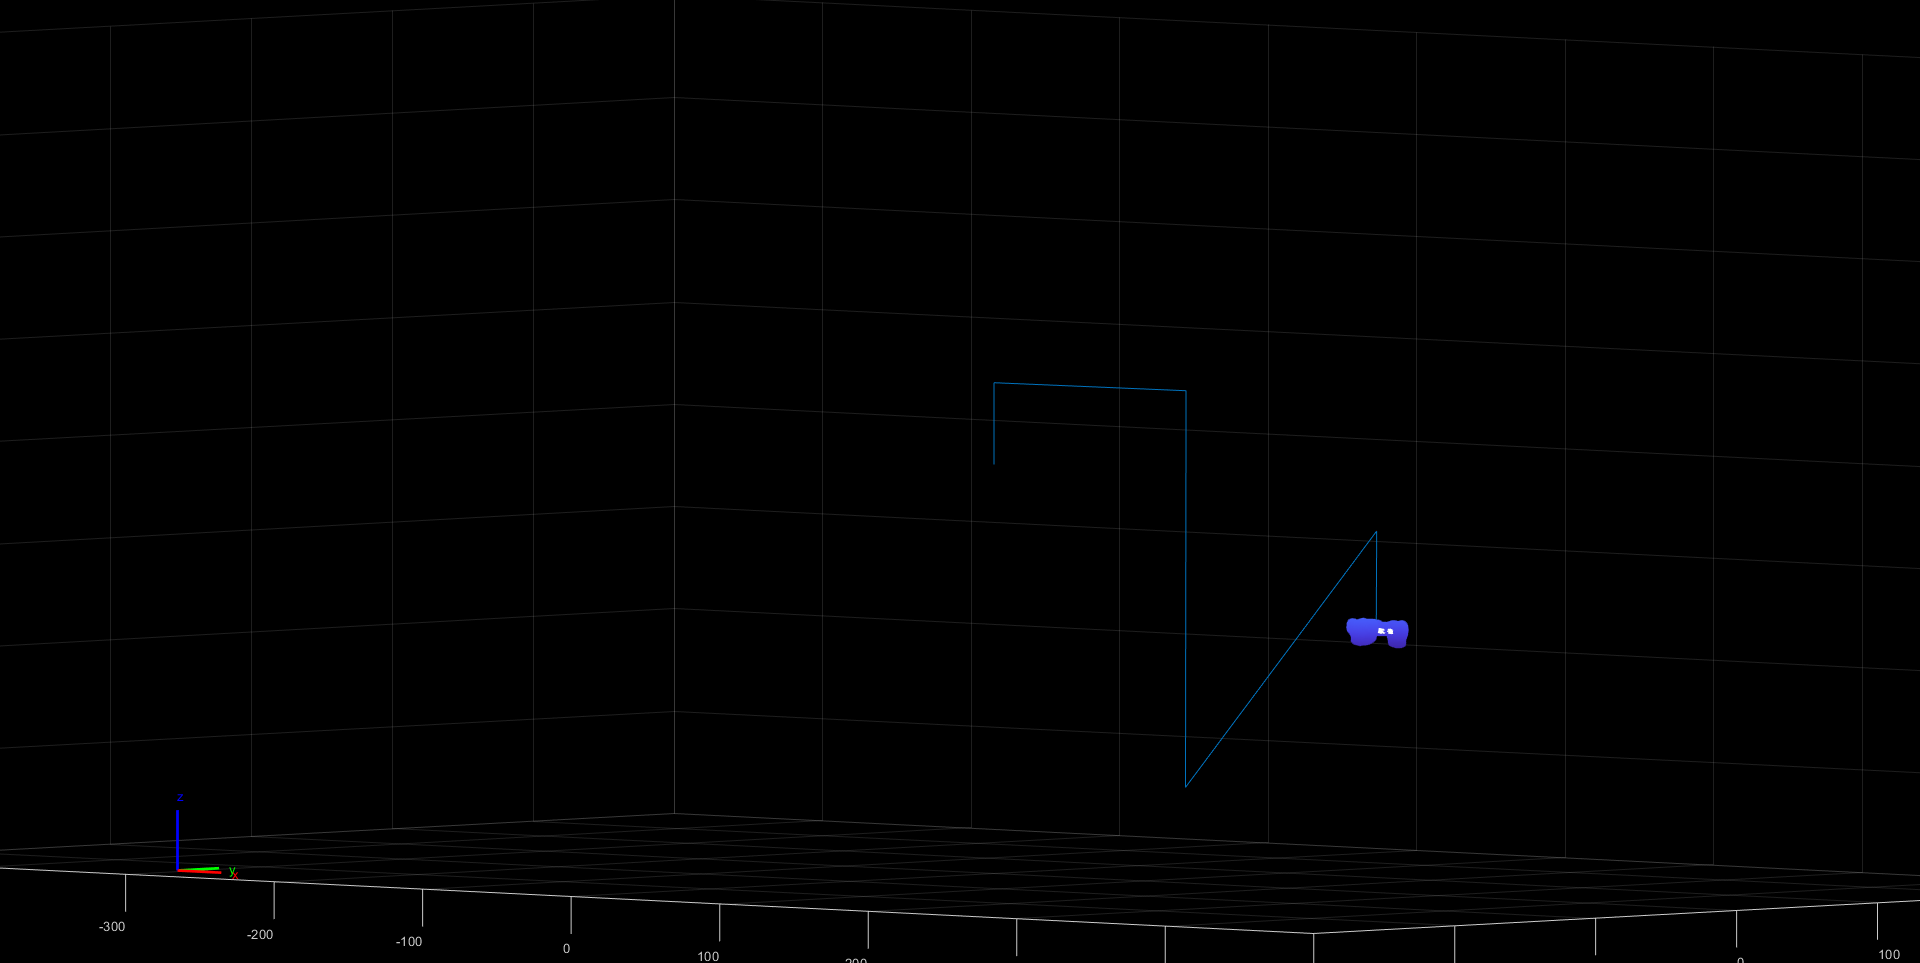

[minimum,ind,ee_arr] = min2pts(dental,q_tot,neighboringTeeth);

figure
pcshow(ptCloud_fin)
hold on
show(dental,home,'PreservePlot',false);
hold on
% plotQuarter(q1_traj_arr); hold on
% plotQuarter(q2_traj_arr); hold on
% plotQuarter(q3_traj_arr); hold on
% plotQuarter(q4_traj_arr); hold on
plotClosest(dental,q_tot,ee_arr,ind,neighboringTeeth);

% plotClosest(dental,q2_config,ee_arr,ind,ptCloud_fin);
% plotClosest(dental,q3_config,ee_arr,ind,ptCloud_fin);


## `Helper Functions`

### `getContour`

function [a,b] = getContour(ptCloud,L,H)
    k = 1;
    
    for i = 1:length(ptCloud.Location(:,3))
        j = ptCloud.Location(i,3);
        if j < H && j > L
            a(k,1) = ptCloud.Location(i,1);
            b(k,1) = ptCloud.Location(i,2);
            k = k+1;
        end
    end
end

### `getOrderedPoints`

function [P] = getOrderedPoints(a,b)
    P = [a'; b']; % coordinates / points 
    c = mean(P,2); % mean/ central point 
    d = P-c ; % vectors connecting the central point and the given points 
    th = atan2(d(2,:),d(1,:)); % angle above x axis
    [th, idx] = sort(th);   % sorting the angles 
    P = P(:,idx); % sorting the given points
    P = [P P(:,1)]; % add the first at the end to close the polygon 
end

### `smoothCurve`

function [smoothX, smoothY] = smoothCurve(P,windowWidth,polynomialOrder)
    smoothX = sgolayfilt(P(1,:), polynomialOrder, windowWidth);
    smoothY = sgolayfilt(P(2,:), polynomialOrder, windowWidth);
end

### `getQuarters`

function [q1,q2,q3,q4] = getQuarters(curve1,flag)    
    a = floor(length(curve1)/4);
%     curve1 = circshift(curve1,floor(a/2));
    curve1 = [curve1; curve1(1,:)];
    q1 = [curve1((1:a),1),curve1((1:a),2),curve1((1:a),3)];
    q2 = [curve1((a:2*a),1),curve1((a:2*a),2),curve1((a:2*a),3)];
    q3 = [curve1((2*a:3*a),1),curve1((2*a:3*a),2),curve1((2*a:3*a),3)];
    q4 = [curve1((3*a:end),1),curve1((3*a:end),2),curve1((3*a:end),3)];
    
    if(flag==1)
        plot3(q1(:,1),q1(:,2),q1(:,3),"LineWidth",1);hold on;
        plot3(q2(:,1),q2(:,2),q2(:,3),"LineWidth",1);hold on;
        plot3(q3(:,1),q3(:,2),q3(:,3),"LineWidth",1);hold on;
        plot3(q4(:,1),q4(:,2),q4(:,3),"LineWidth",1);hold on;
    end
end

function [ax, figHandle] = exampleHelperVisualizeCollisionEnvironment(collisionObjectArray)
%exampleHelperVisualizeCollisionEnvironment Visualize a set of collision objects
%   given a cell array of collision objects, create a figure that plots
%   these and with hold on. Return the handle to the figure's axis.
figHandle = figure;

% Show the first object
show(collisionObjectArray{1});

% Get axis properties and set hold
ax = gca;
hold all;

% Show remaining objects
for i = 2:numel(collisionObjectArray)
    show(collisionObjectArray{i}, "Parent", ax);
end

% Set axis properties
axis equal;

end

### `Closest Point Function:`

function [minimum,ind,ee_arr] = min2pts(bot,traj,ptCloud)
    hyp = zeros(length(ptCloud.Location(:,1)),length(traj(1,:)));
    ee_arr = zeros(length(traj(1,:)),3);
    
    for i = 1:1:length(traj(1,:))
        transform = getTransform(bot,traj(:,i),'Body7','base');
        ee = transform(1:3,4);
        ee_arr(i,:) = transpose(ee);
        d = abs(bsxfun(@minus, ee_arr(i,:), ptCloud.Location));
        hyp(:,i) = sqrt(d(:,1).^2 + d(:,2).^2 + d(:,3).^2); %Store hyp of each point at each frame
    end
    
    [minimum,ind] = min(hyp);
end

### `Plot Distance between ee and closest point function:`

function [] = plotClosest(bot,traj,ee_arr,ind,ptCloud)
    fps = 5;
    r = rateControl(fps);
    set(gcf,'Visible','on')
    pcshow(ptCloud)
    hold on
    axis(1000*[-0.5 0.5 -0.3 0.3 -0.2 0.2])
    for i = 1:1:length(traj(1,:))
        show(bot,traj(:,i),'PreservePlot',false);
        drawnow
        waitfor(r);
        hold on
        line([ee_arr(i,1) ptCloud.Location(ind(i),1)],[ee_arr(i,2) ptCloud.Location(ind(i),2)],[ee_arr(i,3) ptCloud.Location(ind(i),3)],'Color','w')
%         plot3(ee_arr(i,1),ee_arr(i,2),ee_arr(i,3),'Marker','.');
    end
end

### `Order Trajectory based on quarters:`

function [q_traj_arr] = orderQuarter(q_arr)
    %Construct q1 trajectory
    %Start from upper and outer contour
    len_q_z = length(q_arr(:,1)) - 2; %Exclude upper two bc top of tooth
    len_q_c = length(q_arr(1,:)); %Number of contours
    
    
    for j = 0:len_q_c-1 %Different contours
        for i = 0:len_q_z-1 %Different z levels
            q_traj = q_arr{len_q_z-i,len_q_c-j};
            if j == 0 && i == 0 %Need to initialize q1_traj_arr
                q_traj_arr = q_traj;
            else
                if mod(i,2) ~=0  %Reverse every other path
                    q_traj = flipud(q_traj);
                end
                q_traj_arr = vertcat(q_traj_arr,q_traj); %Append to bottom of array
            end
        end
    end
end

### `Plot Quarter Trajectory:`

function [] = plotQuarter(q_traj_arr)
    labels = cellstr( num2str([1:length(q_traj_arr(:,1))]') );
    
    plot3(q_traj_arr(:,1),q_traj_arr(:,2),q_traj_arr(:,3),"LineWidth",1);
    text(q_traj_arr(:,1),q_traj_arr(:,2),q_traj_arr(:,3), labels, 'VerticalAlignment','bottom', ...
                                 'HorizontalAlignment','right')
end

### `Finding Home Config`

function homeConfig = findHomeConfig(ptCloud_fin)
    x_max = max(ptCloud_fin.Location(:,1));
    x_min = min(ptCloud_fin.Location(:,1));
    y_max = max(ptCloud_fin.Location(:,2));
    y_min = min(ptCloud_fin.Location(:,2));
    x = (x_max + x_min)/2;
    y = (y_max + y_min)/2;
    z = -0.04;
    homeConfig = [x y z];
end

### `Check if path in collision or not`

function [isTrajectoryInCollision, a] = isInCollision(q, collisionMesh, robot)
    worldCollisionArray = {collisionMesh};
%     ik = inverseKinematics("RigidBodyTree",robot);
%     weights = ones(1,6);
%     
%     rng(0); % start with a fixed seed to get repeatable results.
%     startConfig = ik("Body5",startPose,weights,robot.homeConfiguration);
%     endConfig = ik("Body5",endPose,weights,robot.homeConfiguration);
%     
%     
%     t = 200;
%     q = trapveltraj([homeConfiguration(robot),startConfig,endConfig],t,"EndTime",2);
    
    % Initialize outputs
    inCollision = false(length(q), 1); % Check whether each pose is in collision
    worldCollisionPairIdx = cell(length(q),1); % Provide the bodies that are in collision
    
    for i = 1:length(q)
        
        [inCollision(i),sepDist] = checkCollision(robot,q(:,i),worldCollisionArray,"IgnoreSelfCollision","on","Exhaustive","on");
        [bodyIdx,worldCollisionObjIdx] = find(isnan(sepDist)); % Find collision pairs
        worldCollidingPairs = [bodyIdx,worldCollisionObjIdx]; 
        worldCollisionPairIdx{i} = worldCollidingPairs;
        
    end
    
    %see if there is any collision
    isTrajectoryInCollision = any(inCollision);
    a = inCollision;
end